clear all

t = (0:0.01:0.99)'

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900



timesteps = 20

timesteps = 20


t=linspace(0,1,timesteps+1)'

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


t(end)=[];

M = 0.5*[1 -2 1; -2 2 1; 1 0 0];

knots = 4

knots = 4

index= [];

output1 = sin(exp(t)+sin(10*t).^2+3*cos(3*t)+0.3*rand(timesteps,1));
output2= cos(5*t)+0.4*rand(timesteps,1)

output2 =     1.3007
    1.1163
    1.2543
    0.7386
    0.8719
    0.5660
    0.2862
    0.0820
   -0.1255
   -0.5904



output_curve = outproduct(output1,output2);

Y = output_curve(:)

Y =    -1.0114
   -1.2318
   -1.2939
   -1.2382
   -1.2988
   -1.0236
   -0.4517
    0.1183
   -0.0987
   -0.2293


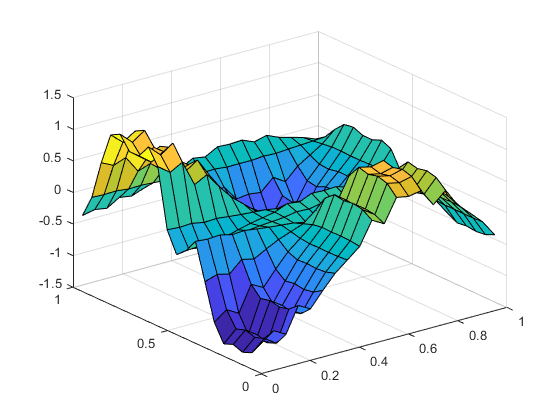


% output_curve(1:80,1:80)=0
surf(t,t,output_curve);

% 
% plot(output1)
% plot(output2)

N=zeros(length(t),knots+2);
B=[]


B =

     []



C=[]


C =

     []




for i=1:length(t)
   index(i)= floor((t(i)*knots+(10*knots*eps)))+1;
    Ntemp = (mod(t(i),1/knots)*knots).^linspace(2,0,3)*M';
%     Ntemp = (t(i)-(index(i)-1)/timesteps/knots).^linspace(2,0,3)*M';
    N(i,index(i):index(i)+2) = Ntemp;
end

for ii= 1:timesteps
    for jj=1:timesteps

N_multi = outproduct(N(ii,:),N(jj,:));
   B(jj,:)=N_multi(:)';
    end
    C = [C ; B];
end


% -------------------------------------
tic
Theta=zeros(36,1)

Theta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Pcov =eye(36)*1000

Pcov =         1000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0        1000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0           0        1000           0           0           0           0           0           0           0       



for kk=1:400
    
Phi = C(kk,:);

Pcov = Pcov - (Pcov * Phi'*Phi * Pcov)/(1+Phi*Pcov*Phi');

epsil = Y(kk) - Phi * Theta;

K = Pcov*Phi';
Theta = Theta + K *epsil;

end
toc

Elapsed time is 0.027721 seconds.


% -----------------------------------
tic
P=pinv(C)*output_curve(:) ;
toc

Elapsed time is 0.006667 seconds.


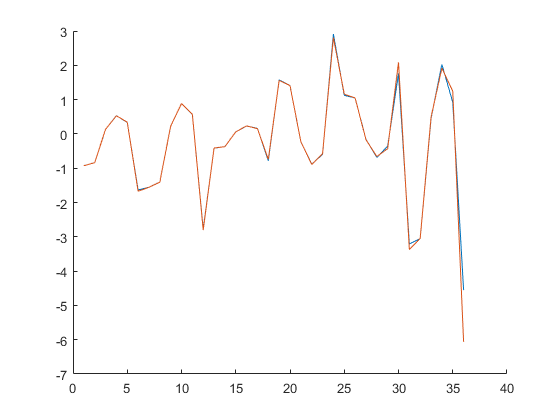


y=C*P;
y=C*Theta;

figure;
hold on
plot(Theta)
plot(P)
hold off

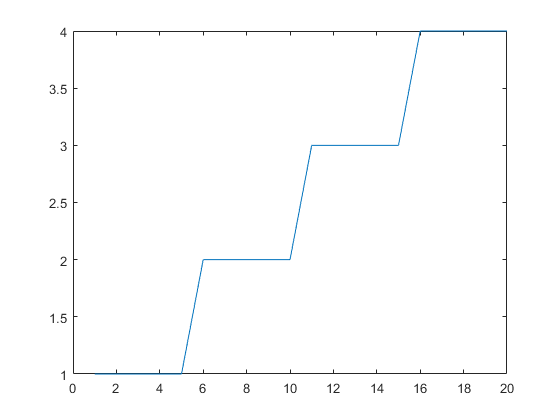


plot(index)

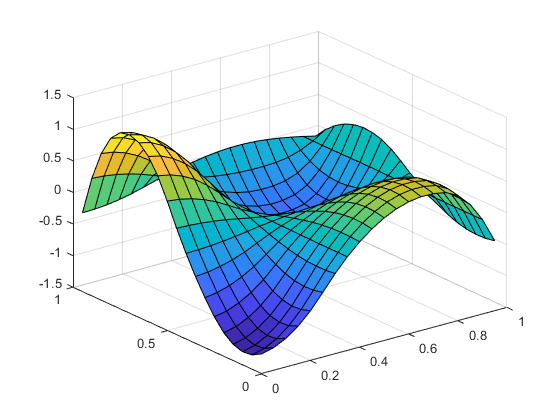

surf(t,t,reshape(y,[timesteps timesteps]))

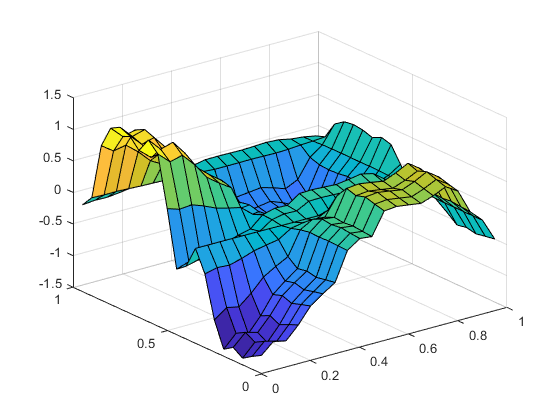

surf(t,t,output_curve)

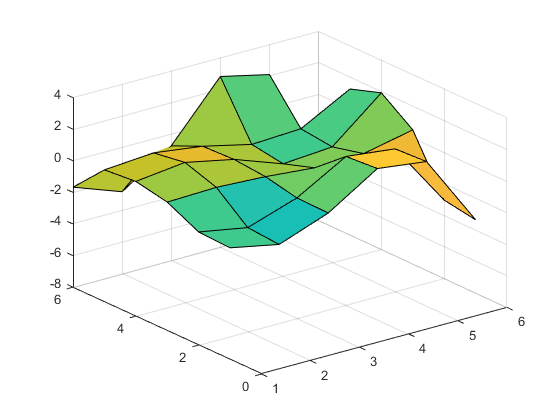


surf(1:knots+2,1:knots+2,reshape(P,[knots+2 knots+2]))


norm(reshape(y,[timesteps timesteps])-output_curve)

ans = 2.5847


% surf(t,t,abs(reshape(y,[timesteps timesteps])-output_curve))



[coeff,score,latent] = pca(reshape(P,[knots+2 knots+2]))

coeff =     0.2476    0.8331   -0.2453    0.2473   -0.2234
    0.4938   -0.3012   -0.1088   -0.4848   -0.2936
    0.1054    0.0667   -0.1167   -0.0237    0.9138
   -0.4806    0.2916    0.6516   -0.3248   -0.0478
   -0.2633   -0.3535   -0.0259    0.6964   -0.1487
    0.6192   -0.0283    0.6994    0.3358    0.0675


score =    -1.9572    0.0000   -0.0000   -0.0000   -0.0000
   -2.0124    0.0000    0.0000    0.0000   -0.0000
    1.3779    0.0000    0.0000   -0.0000    0.0000
    3.3193   -0.0000   -0.0000    0.0000   -0.0000
    1.3193    0.0000    0.0000   -0.0000   -0.0000
   -2.0469   -0.0000   -0.0000   -0.0000   -0.0000


latent =     5.3454
    0.0000
    0.0000
    0.0000
    0.0000


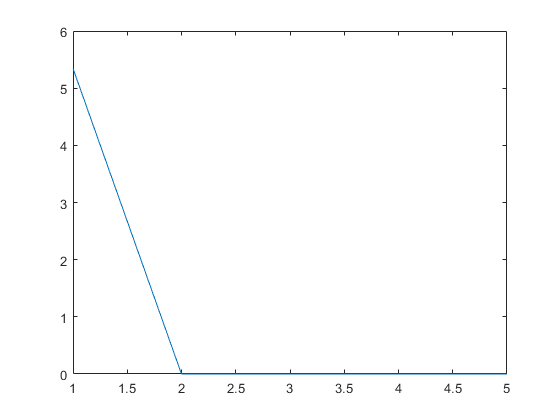


plot(latent)